## Data loading

% This is the .m file produced by Main.mlx
load('CancerDriverGenes_20240621_222151.mat')

referenceGenesList = readtable('general_driver_list.csv', 'ReadVariableNames', false);
referenceGenesList = referenceGenesList.Var1;

## Get reference general cancer driver genes

numSamples = size(mutMatrix, 2);
personalReferences = cell(numSamples, 1);
deletedSampleLess3 = [];

for i = 1:numSamples
    sampleMutations = mutMatrix{:, i} == 1; 
    mutatedGenes = mutMatrix.Properties.RowNames(sampleMutations);
    personalRef = intersect(mutatedGenes, referenceGenesList);
    
    if length(personalRef) < 3
        deletedSampleLess3 = [deletedSampleLess3; i];
    else
        personalReferences{i} = personalRef;
    end
end
personalReferences(deletedSampleLess3) = [];
rankForSamples(deletedSampleLess3) = [];
numValidSamples = numSamples - length(deletedSampleLess3);

## Get dynamic N  for given cancer

personalRefSizes = cellfun(@length, personalReferences);
sortedSizes = sort(personalRefSizes);
medianSize = median(sortedSizes);
dynamicN = round(medianSize) * 2;
% dynamicN = 8;

## Precision, recall and F1

allSamplesPRF1 = cell(numValidSamples, dynamicN);

for i = 1:numValidSamples
    personalRef = personalReferences{i};
    predictedGenes = rankForSamples{i};
    
    for k = 1:dynamicN
        if k > length(predictedGenes)
            break;
        end
        
        topKPredicted = predictedGenes(1:k, 1);
        intersectionCount = length(intersect(personalRef, topKPredicted));
        
        precision = intersectionCount / k;
        recall = intersectionCount / length(personalRef);
        
        if precision + recall == 0
            f1score = 0;
        else
            f1score = 2 * precision * recall / (precision + recall);
        end
        
        allSamplesPRF1{i, k} = [precision, recall, f1score];
    end
end

avgPrecision = zeros(1, dynamicN);
avgRecall = zeros(1, dynamicN);
avgF1score = zeros(1, dynamicN);

for k = 1:dynamicN
    validSamples = [];
    
    for i = 1:numValidSamples
        if ~isempty(allSamplesPRF1{i, k})
            validSamples = [validSamples; allSamplesPRF1{i, k}];
        end
    end
    
    if ~isempty(validSamples)
        avgPrecision(k) = mean(validSamples(:, 1));
        avgRecall(k) = mean(validSamples(:, 2));
        avgF1score(k) = mean(validSamples(:, 3));
    end
end

## Plot

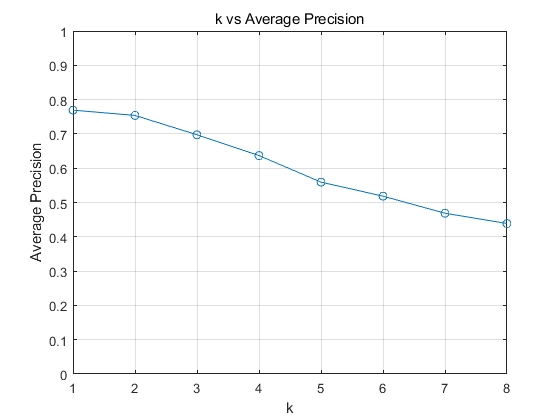

% Precision
figure;
plot(1:dynamicN, avgPrecision, '-o');
xlabel('k');
ylabel('Average Precision');
title('k vs Average Precision');
ylim([0, 1]);
grid on;

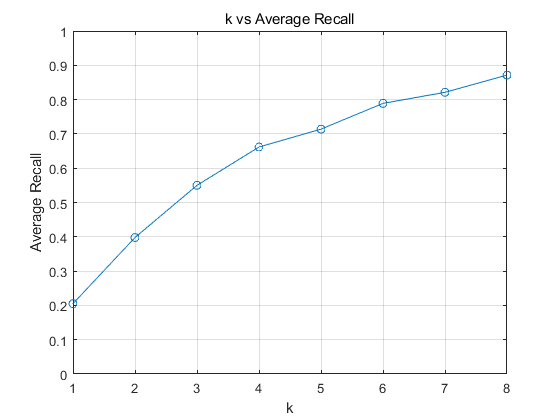


% Recall
figure;
plot(1:dynamicN, avgRecall, '-o');
xlabel('k');
ylabel('Average Recall');
title('k vs Average Recall');
ylim([0, 1]);
grid on;

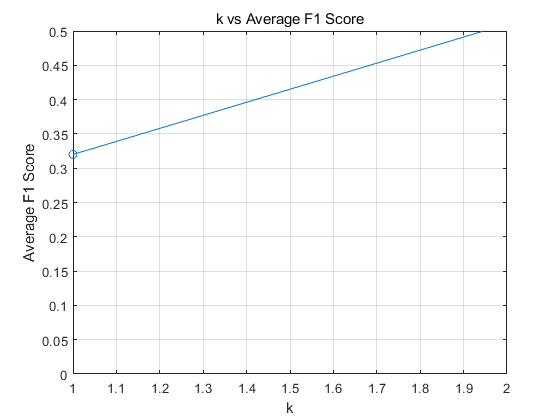


% F1 Score
figure;
plot(1:dynamicN, avgF1score, '-o');
xlabel('k');
ylabel('Average F1 Score');
title('k vs Average F1 Score');
ylim([0, 0.5]);
grid on;